% I'll start with simulating a data matrix.
rng(9)
n_timepoints = 15;
n_observations = 1;
data_matrix = zeros(n_observations, n_timepoints);
s_true = 0.9

s_true = 0.9000

rho = 0.8

rho = 0.8000


for i=1:n_observations
    first_value = normrnd(0,s_true,1);
    data_matrix(i,1) = first_value;
    for j = 2:n_timepoints
        data_matrix(i,j) = rho*data_matrix(i,j-1) + normrnd(0,s_true,1);
    end
end

true_covariance = zeros(n_timepoints, n_timepoints);
for i=1:n_timepoints
    for j=1:n_timepoints
        true_covariance(i,j) = rho^(abs(i-j));
    end
end
true_covariance = true_covariance.*((s_true.^2)/(1-rho.^2))

true_covariance =     2.2500    1.8000    1.4400    1.1520    0.9216    0.7373    0.5898    0.4719    0.3775    0.3020    0.2416    0.1933    0.1546    0.1237    0.0990
    1.8000    2.2500    1.8000    1.4400    1.1520    0.9216    0.7373    0.5898    0.4719    0.3775    0.3020    0.2416    0.1933    0.1546    0.1237
    1.4400    1.8000    2.2500    1.8000    1.4400    1.1520    0.9216    0.7373    0.5898    0.4719    0.3775    0.3020    0.2416    0.1933    0.1546
    1.1520    1.4400    1.8000    2.2500    1.8000    1.4400    1.1520    0.9216    0.7373    0.5898    0.4719    0.3775    0.3020    0.2416    0.1933
    0.9216    1.1520    1.4400    1.8000    2.2500    1.8000    1.4400    1.1520    0.9216    0.7373    0.5898    0.4719    0.3775    0.3020    0.2416
    0.7373    0.9216    1.1520    1.4400    1.8000    2.2500    1.8000    1.4400    1.1520    0.9216    0.7373    0.5898    0.4719    0.3775    0.3020
    0.5898    0.7373    0.9216    1.1520    1.4400    1.8000    2.2500    1.


solve_this = @(a) (ar1_constraint(a));
% options = optimoptions('fsolve','Display','None','TolFun', ...
%         8e-6, 'MaxFunctionEvaluations', 3e5, 'MaxIterations', 3e5);
[U, Lambda2] = eig(true_covariance);
Lambda = diag(diag(Lambda2.^(0.5)));
original_sign = sign(det(U));
my_count = 0;
[d,~] = size(Lambda);
for i = 0:(2^d-1)
    temp_signs = de2bi(i,d);
    temp_signs = 2*temp_signs(1:d)-1;
    if(1==original_sign*prod(temp_signs))
        tempUhat = U*diag(temp_signs);
        % put an if statement here.
        tempA = (eye(d) - tempUhat)/(eye(d) + tempUhat);
        temp_vector = collapseParameters(tempA,Lambda);
        E = eig(tempUhat);
        if( 1 == prod(temp_vector((d+1):end)>-1 & temp_vector((d+1):end)<1) & sum(real(E)==-1)==0)
            disp("got here");
            [actualA,~] = uncollapseParameters(temp_vector);
            actualU = tempUhat;
            initial_guess = temp_vector
            break
        end
    end
end

got here


initial_guess =     0.5027
    0.5109
    0.5250
    0.5459
    0.5748
    0.6137
    0.6656
    0.7352
    0.8300
    0.9625



num_iters = 1000;
burn_in = 1;
proposal_scale = 3e-5

proposal_scale = 3.0000e-05


ll_function = @(x) ll_density(x, data_matrix);
constraintFunc = @(x) (ar1_constraint(x));
dConstraintFunc = @(x) (dar1_constraint(x));

warning('off');
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess, ll_function, ...
    constraintFunc, dConstraintFunc);

Acceptance rate (so far): 1.
Iteration number is: 1.
-----------
Acceptance rate (so far): 1.
Iteration number is: 2.
-----------
Acceptance rate (so far): 6.666667e-01.
Iteration number is: 3.
-----------
Acceptance rate (so far): 5.000000e-01.
Iteration number is: 4.
-----------
Acceptance rate (so far): 4.000000e-01.
Iteration number is: 5.
-----------
Acceptance rate (so far): 5.000000e-01.
Iteration number is: 6.
-----------
Acceptance rate (so far): 4.285714e-01.
Iteration number is: 7.
-----------
Acceptance rate (so far): 3.750000e-01.
Iteration number is: 8.
-----------
Acceptance rate (so far): 4.444444e-01.
Iteration number is: 9.
-----------
Acceptance rate (so far): 4.000000e-01.
Iteration number is: 10.
-----------
Acceptance rate (so far): 3.636364e-01.
Iteration number is: 11.
-----------
Acceptance rate (so far): 3.333333e-01.
Iteration number is: 12.
-----------
Acceptance rate (so far): 3.076923e-01.
Iteration number is: 13.
-----------
Acceptance rate (so far): 2.85

mean(accepts)

ans = 0.1090

save("setseed_MH_ar1_Draws.mat",'samples');
save("MH_accepts_truevalue.mat", "accepts");

## Use the samples to calculate values for rho and sigma2:

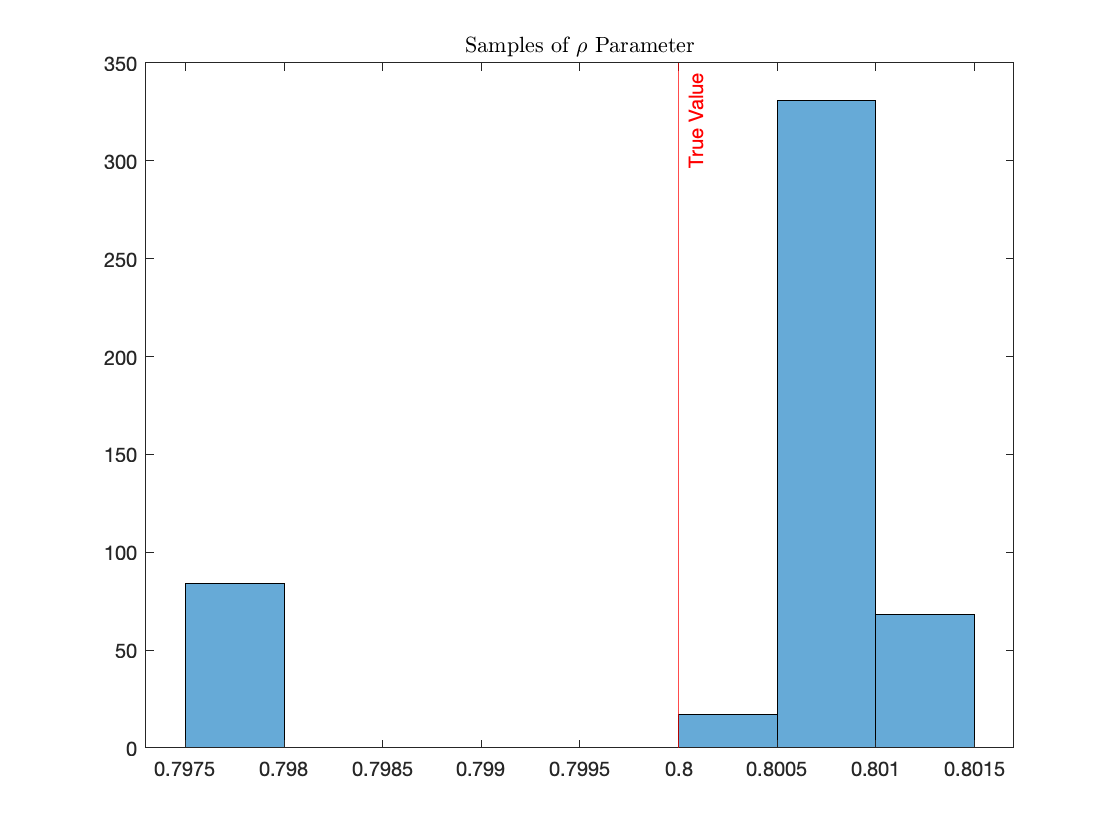

samples = load("setseed_MH_ar1_Draws.mat");
samples = samples.samples;
accepts = load("MH_accepts_truevalue.mat");
accepts = accepts.accepts;
mean(accepts);

[~,num_of_samples] = size(samples);
burnin = 500;
rhos = zeros(1,num_of_samples-burnin);
s2s = zeros(1,num_of_samples-burnin); 

for i=1:(num_of_samples-burnin)
    [A, Lambda] = uncollapseParameters(samples(:,i+burnin));
    U = (eye(n_timepoints) - A)/(eye(n_timepoints) + A);
    sigma = U*(Lambda.^2)*(U');
    rhos(i) = sigma(1,2)/sigma(1,1);
    s2s(i) = sigma(1,1)*(1 - (sigma(1,2)/sigma(1,1)).^2);
end

histogram(rhos);
hold on
xline(rho, 'label', 'True Value', 'Color','r');
t = 'Samples of $\rho$ Parameter';
title(t,'interpreter','latex')
hold off

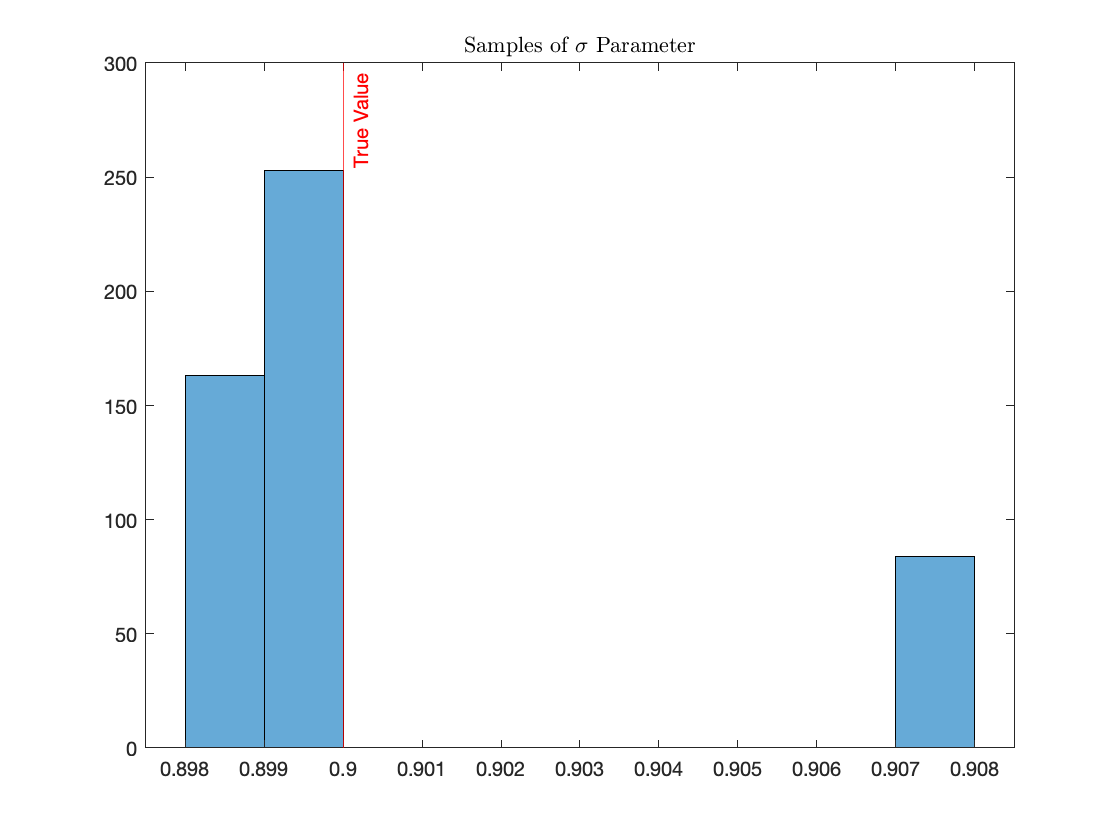


histogram(sqrt(s2s));
hold on
xline(s_true, 'label', 'True Value', 'Color', 'r');
t = 'Samples of $\sigma$ Parameter';
title(t,'interpreter','latex')
hold off